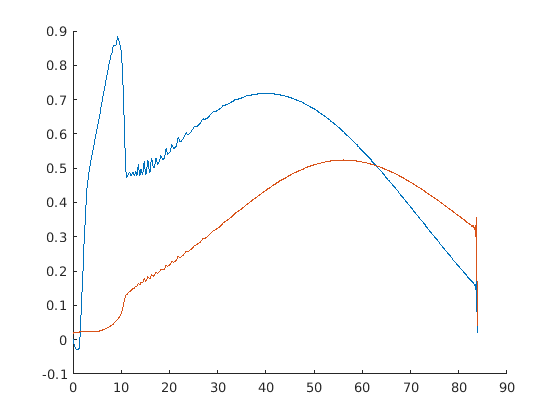

csv = csvread('1.csv');
a = csv(:,1);
cl = csv(:,2);
cd = csv(:,3);
cdp = csv(:,4);
cm = csv(:,5);
topxtr = csv(:,6);
botxtr = csv(:,7);
topitr = csv(:,8);
botitr = csv(:,9);

hold off;
%plot(a, cl);
hold on;
%plot(a, cd);

[cl_s, a_cl_s] = resample(cl, a, 10, 'spline');
plot(a_cl_s, cl_s);
[cd_s, a_cd_s] = resample(cd, a, 10, 'spline');
plot(a_cd_s, cd_s);
%scatter(a, cl);
%scatter(a, cd);

bwlpf = designfilt('lowpassiir', 'PassbandFrequency', 0.1, 'StopbandFrequency', 0.2, ...
'PassbandRipple', 0.5, 'StopbandAttenuation', 65, 'DesignMethod', 'butter', ...
'SampleRate', 1/(a_cl_s(2)-a_cl_s(1)) ...
);

firlpf = designfilt('lowpassfir', 'PassbandFrequency', 0.1, 'StopbandFrequency', 0.2, ...
'PassbandRipple', 0.5, 'StopbandAttenuation', 65, 'DesignMethod', 'equiripple', ...
'SampleRate', 1/(a_cl_s(2)-a_cl_s(1)) ...
);

[A, B, C, D]=ss(firlpf);
firlpf_ss = ss(A, B, C, D, 1/firlpf.SampleRate);
[A, B, C, D] = ss(bwlpf);
bwlpf_ss = ss(A, B, C, D, 1/firlpf.SampleRate);

%firlpf.freqz;
%bwlpf.freqz;

hold off;

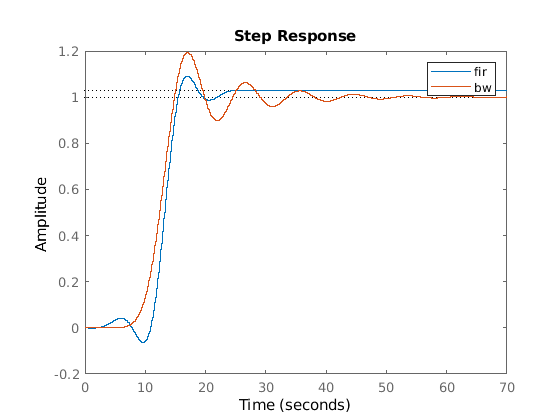

step(firlpf_ss);
hold on;
step(bwlpf_ss);
legend('fir', 'bw');

hold off;

fir_x0 = zeros(size(firlpf_ss, 1), 1);
bw_x0 = zeros(size(bwlpf_ss, 1), 1);
fir_out = lsim(firlpf_ss, cl_s, a_cl_s);
bw_out = lsim(bwlpf_ss, cl_s, a_cl_s);

hold off;

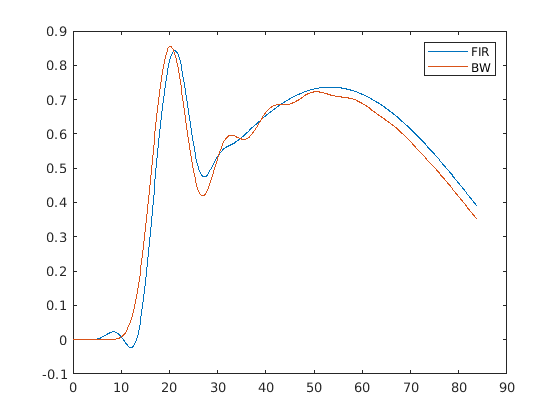

plot(a_cl_s, fir_out);
hold on;
plot(a_cl_s, bw_out);
legend('FIR', 'BW');


%alpha    CL        CD       CDp       CM     Top_Xtr  Bot_Xtr  Top_Itr  Bot_Itr